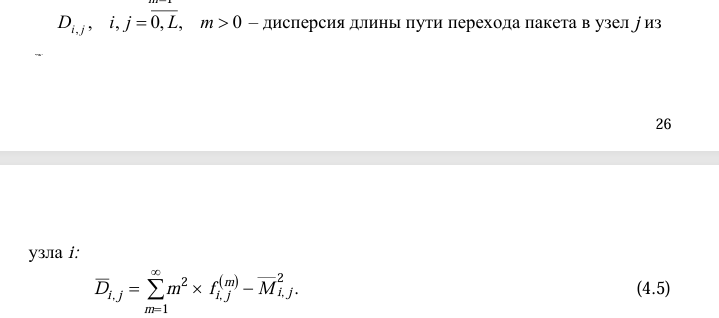

% Функция для вычисления дисперсии длины пути
function var_length = variance_path_length(P, i, j, epsilon)
    m = 1;
    exp_length = expected_path_length(P, i, j, epsilon);
    var_length = 0;
    while true
        prob = first_passage_probability(P, i, j, m);
        var_length = var_length + m^2 * prob;
        if prob <= epsilon
            break;
        end
        m = m + 1;
    end
    var_length = var_length - exp_length^2;
end